clc;
clear;
close all;

SetStdPlot();


tb=readmatrix("E:\VScode\Proj_Molecular3D\File\TestOutputOpt\TimeRecord\C1=CC2=C(C3=C(C=CC4=C3C5=C(C=C4)C=CC6=C5C=CC=C6)C=C2)C=C1_20251115_070010.csv")

tb = 1.0e+07 *

    0.0000    0.0000    1.1710
    0.0000    0.0000    0.0728
    0.0000    0.0000    0.0002
    0.0001    0.0000    0.0002
    0.0001    0.0000    0.0000
    0.0001    0.0000    0.0000
    0.0001    0.0000    0.0000
    0.0001    0.0000    0.0000
    0.0002    0.0000    0.0000
    0.0002    0.0000    0.0000


[lwidth,msize,sep]=deal(1.5,4,10);
[acolor,bcolor,ccolor,dcolor]=deal('#79D9DB','#80B8EA',"#C2B3D1","#E8BDDF")

acolor = '#79D9DB'

bcolor = '#80B8EA'

ccolor = "#C2B3D1"

dcolor = "#E8BDDF"

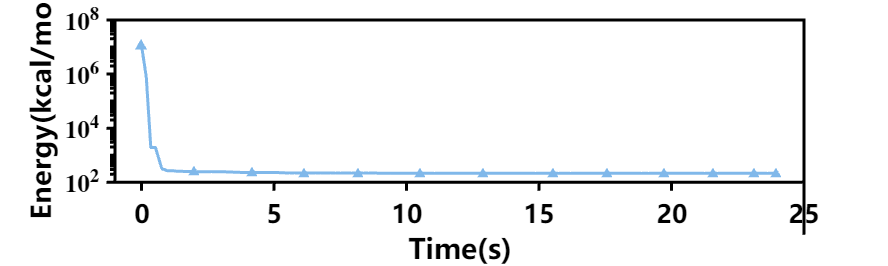


time=tb(:,1)/1000;
energy=tb(:,3);

figure;
SetAxesLog(gca,[],[10^(2),10^8],0,1)
PlotScatterline("",[time,energy],sep,'-','^',lwidth,msize,bcolor);

yticks(10.^(2:2:8))
yticklabels({'10^2','10^4','10^6','10^8'})
xlim([-1,25])
xlabel("Time(s)")
ylabel("Energy(kcal/mol)")

PlotRULine(gca,'k','k',1.5)

set(gcf, 'Position', [0, 0, 1000, 300]); % [left, bottom, width, height]
print(gcf, 'ET', '-dpng'); 